Testing Data

clc; clear; close all;

%%Create Data Stores
d1 = "stage_2_test_images/Test_Positive/";
Pfiles = dir(fullfile(d1));
Pfiles([Pfiles.isdir]) = [];
n_Pfiles = length(Pfiles);

d2 = "stage_2_test_images/Test_Negative/";
Nfiles = dir(fullfile(d2));
Nfiles([Nfiles.isdir]) = [];
n_Nfiles = length(Nfiles);

%Labels array
pos_label = strings(n_Pfiles,1);
pos_label(1:end) = "positive";
neg_label = strings(n_Nfiles,1);
neg_label(1:end) = "negative";
labels = [pos_label;neg_label];

%%Initiate variable arrays
LungSize = zeros(size(labels));
AveValues = zeros(size(labels));

Running Positive training images through Image Processing


for i = 1:n_Pfiles
     filename = fullfile(d1, Pfiles(i).name);
%     Read file and gray scale
    img = dicomread(filename);
    img = im2gray(img);
    img = imadjust(img);
%     Invert image 
    testimg = 255 - img;
    testimg_clear = imclearborder(testimg);
    testimg_clear_inv = 255-testimg_clear;
%     Find lungs
    I = testimg_clear_inv;
    [BW, thresh] = edge(I,'sobel');
    fudgeFactor = 0.8;
    Iedge = edge(I,'sobel',fudgeFactor*thresh);
%     Dilate, fill holes, and erode
    se90 = strel('line',6,90);
    se0 = strel('line',3,0);
    Idilate = imdilate(Iedge,[se90, se0]);
    Ifill = imfill(Idilate, 'holes');
    seD = strel('diamond', 3);
    Ierode1 = imerode(Ifill,seD);
    Ierode2 = imerode(Ierode1,seD);
    Ierode3 = imerode(Ierode2,seD);
    Ifinal = imerode(Ierode3,seD);
%     Find variables
    Ave_val = mean(img(Ifinal));
    num_pixels = sum(Ifinal(:));
%     Variable vectors
    LungSize(i) = num_pixels;
    AveValues(i) = Ave_val;
end

Running Negative training images through Image Processing


for j = 1:n_Nfiles
     filename = fullfile(d2, Nfiles(j).name);
%     Read file and gray scale
    img = dicomread(filename);
    img = im2gray(img);
    img = imadjust(img);
%     Invert image 
    testimg = 255 - img;
    testimg_clear = imclearborder(testimg);
    testimg_clear_inv = 255-testimg_clear;
%     Find lungs
    I = testimg_clear_inv;
    [BW, thresh] = edge(I,'sobel');
    fudgeFactor = 0.8;
    Iedge = edge(I,'sobel',fudgeFactor*thresh);
%     Dilate, fill holes, and erode
    se90 = strel('line',6,90);
    se0 = strel('line',3,0);
    Idilate = imdilate(Iedge,[se90, se0]);
    Ifill = imfill(Idilate, 'holes');
    seD = strel('diamond', 3);
    Ierode1 = imerode(Ifill,seD);
    Ierode2 = imerode(Ierode1,seD);
    Ierode3 = imerode(Ierode2,seD);
    Ifinal = imerode(Ierode3,seD);
%     Find variables
    Ave_val = mean(img(Ifinal));
    num_pixels = sum(Ifinal(:));
%     Variable vectors
    LungSize(n_Pfiles+j) = num_pixels;
    AveValues(n_Pfiles+j) = Ave_val;
end
        

Create Output table to be used in Learning Models

%creating the table output
    Model_Table = table(labels,LungSize,AveValues)

Model_Table = 50×3 table
      labels       LungSize     AveValues
    __________    __________    _________

    "positive"         77071     89.534  
    "positive"          1423     75.096  
    "positive"         78691     55.067  
    "positive"           313     146.35  
    "positive"          2360     64.243  
    "positive"         27694     91.299  
    "positive"    1.1828e+05     55.291  
    "positive"         48627     125.27  
    "positive"         52096     89.905  
    "positive"          7079     93.616  
    "positive"    1.2272e+05     44.314  
    "positive"          2013     55.999  
    "positive"         72909     165.21  
    "positive"          1475     55.212  
    "positive"         29563     109.44  
    "positive"    1.3087e+05     71.072  


Load models

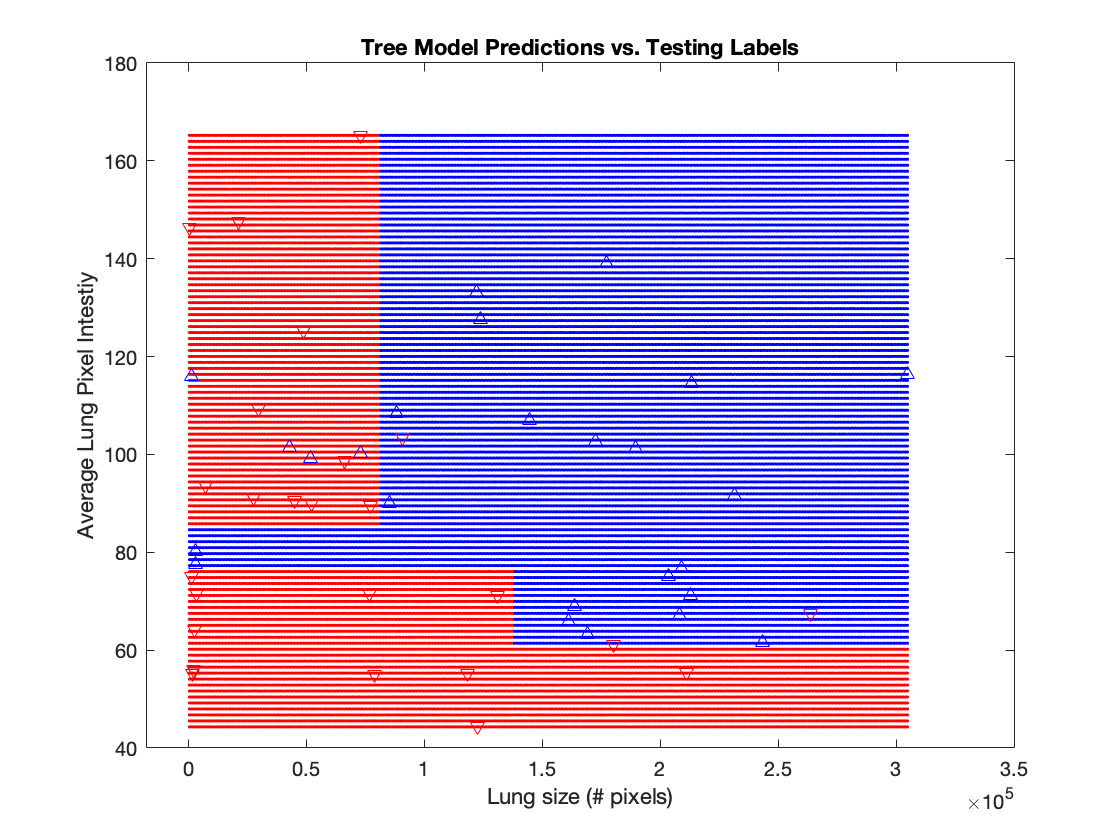

figure(1)
Tree = d_tree(Model_Table);
title('Tree Model Predictions vs. Testing Labels')
xlabel('Lung size (# pixels)')
ylabel('Average Lung Pixel Intestiy')

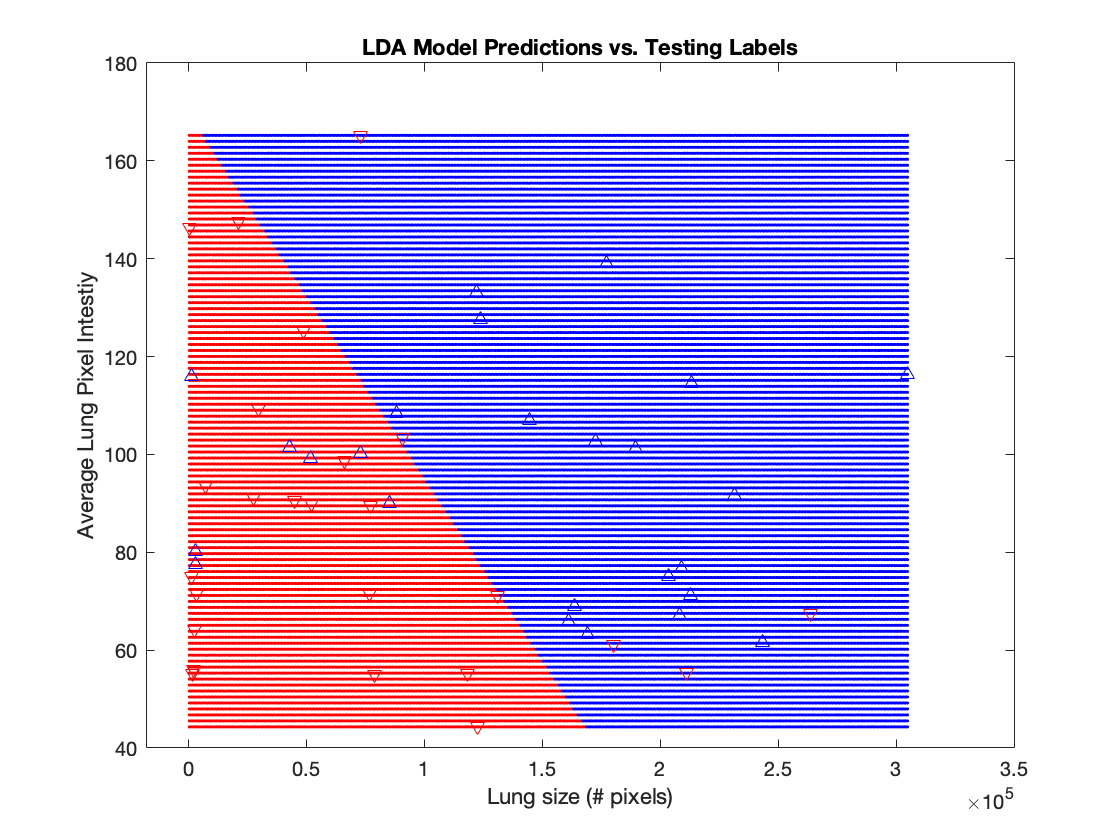

figure(2)
LDA = LDA(Model_Table);
title('LDA Model Predictions vs. Testing Labels')
xlabel('Lung size (# pixels)')
ylabel('Average Lung Pixel Intestiy')

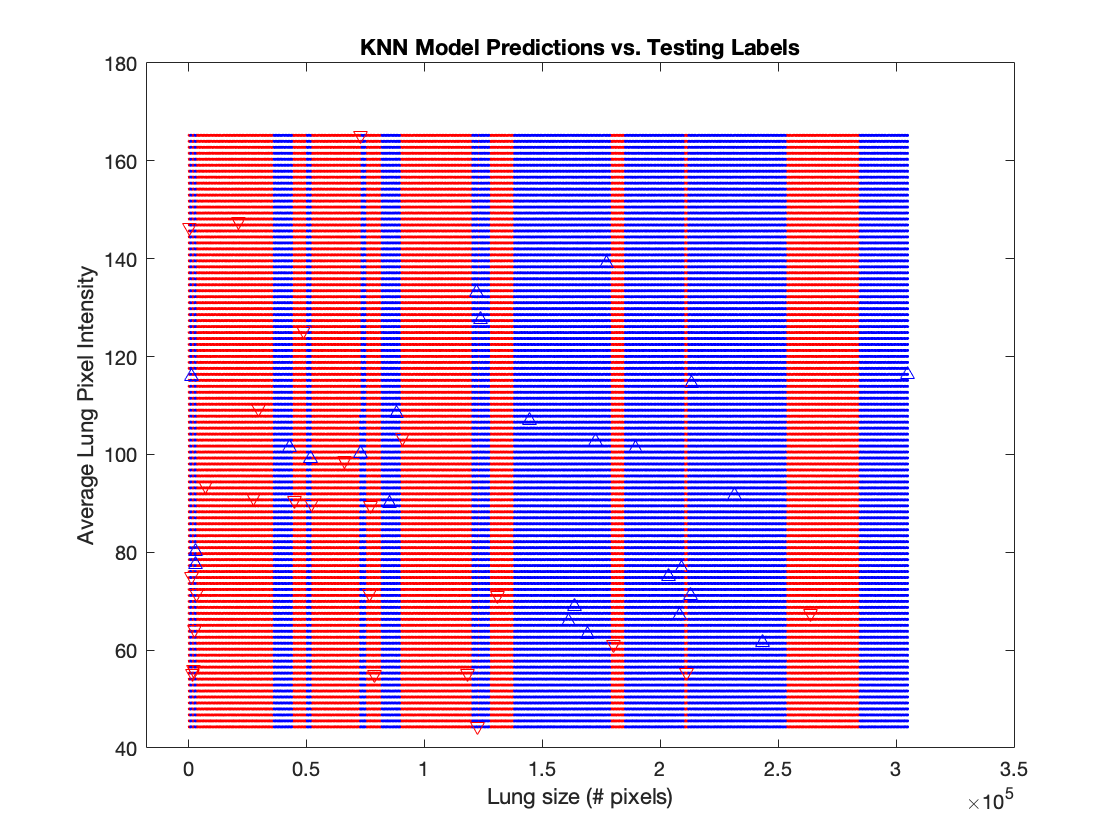

figure(3)
KNN = KNN(Model_Table);
title('KNN Model Predictions vs. Testing Labels')
xlabel('Lung size (# pixels)')
ylabel('Average Lung Pixel Intensity')

Run Models

KNN_predict = KNN.predict([LungSize,AveValues]);

KNN_predict = 50×1 cell array
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'negative'}
    {'negative'}
    {'negative'}
    {'negative'}
    {'negative'}


LDA_predict = LDA.predict([LungSize,AveValues]);

LDA_predict = 50×1 cell array
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'negative'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'negative'}
    {'positive'}
    {'negative'}
    {'negative'}
    {'positive'}
    {'positive'}
    {'negative'}
    {'positive'}
    {'positive'}
    {'negative'}
    {'negative'}
    {'negative'}
    {'negative'}
    {'positive'}


Tree_predict = Tree.predict([LungSize,AveValues]);

Tree_predict = 50×1 cell array
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'negative'}
    {'negative'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'negative'}
    {'negative'}
    {'negative'}
    {'negative'}
    {'negative'}


Confusion Matrices

figure(4)
cell_labels = cellstr(labels)

cell_labels = 50×1 cell array
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'positive'}
    {'negative'}
    {'negative'}
    {'negative'}
    {'negative'}
    {'negative'}


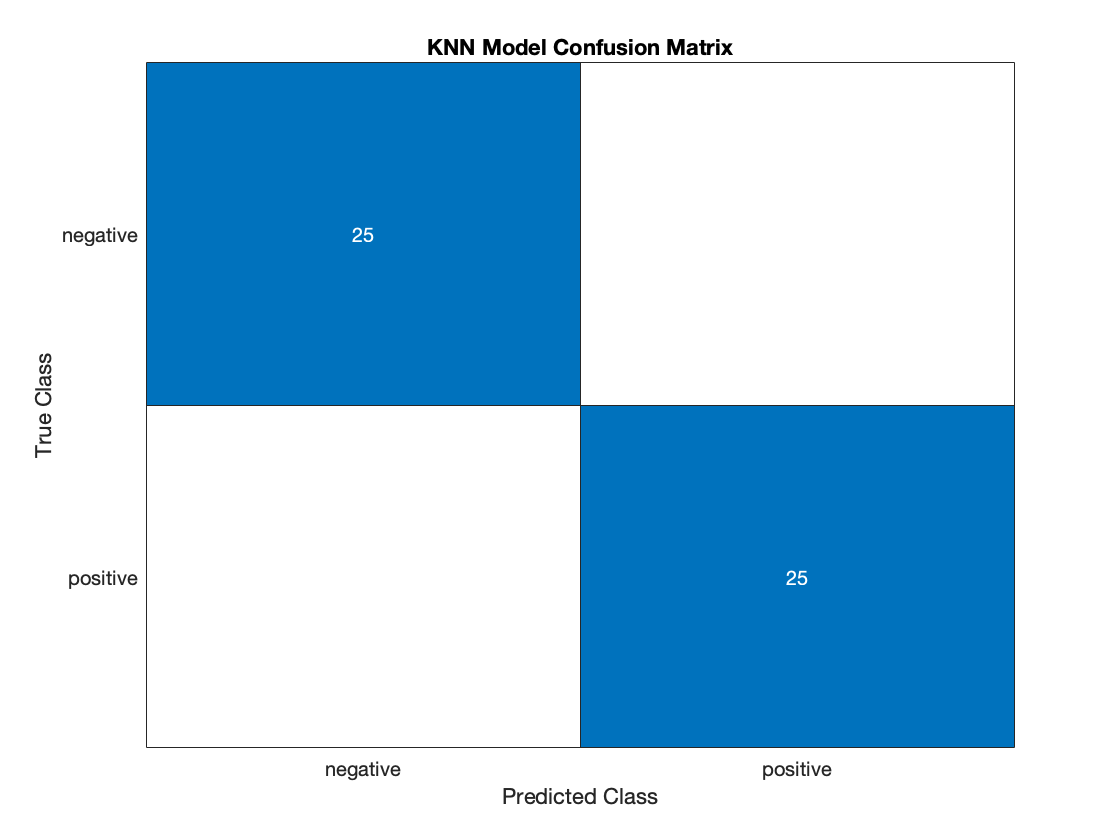

confusionchart(cell_labels,KNN_predict)
title("KNN Model Confusion Matrix");

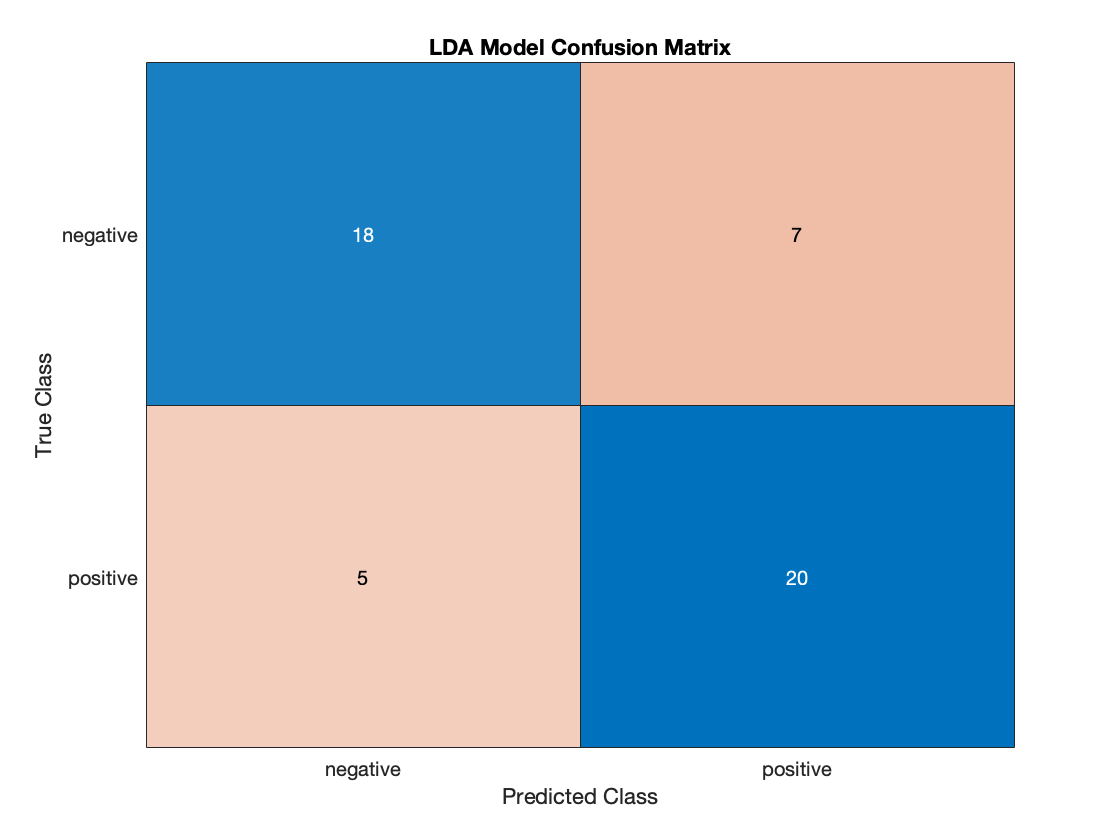


figure(5)
confusionchart(cell_labels,LDA_predict)
title("LDA Model Confusion Matrix");

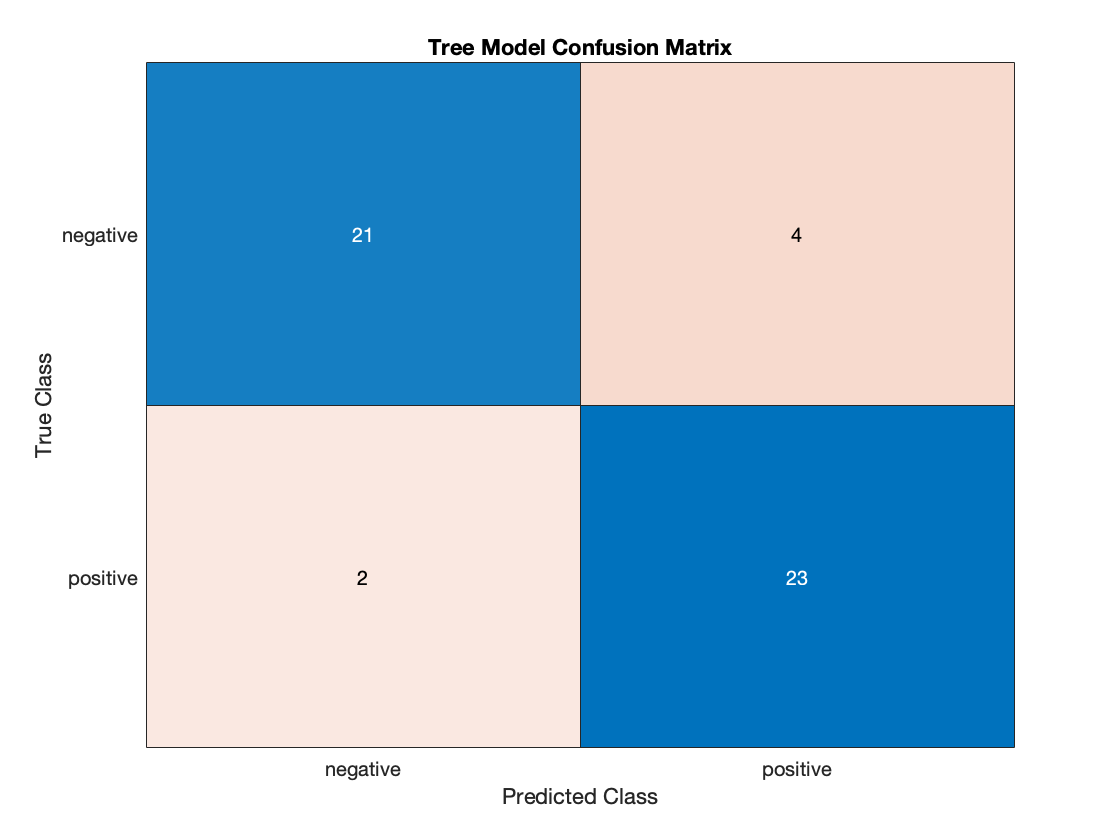


figure(6)
confusionchart(cell_labels,Tree_predict)
title("Tree Model Confusion Matrix");